% -----------Anatomical and Functional Visualizations---------------

% Clear our workspace to prevent interference from previously loaded data
clear

% Load the subject's coordinates

% Using Github Link to Load Coordinates 

%% 1 
table1 = readtable("https://raw.githubusercontent.com/safiy-va/MatLab-Code-for-Brain-as-a-Matrix---Transformations-and-Visualization-/refs/heads/main/Subject200_Centroids.csv")

table1 = 200×3 table
       X          Y         Z   
    _______    _______    ______

    -36.772    -50.949     -10.2
    -44.012    -73.697    -14.28
    -63.305    -65.868     -8.16
    -25.065    -64.399     -4.08
    -47.867    -90.775    -12.24
    -24.127    -41.581     -2.04
    -26.004    -87.218     -4.08
    -65.406    -65.844      10.2
    -43.665    -90.823      6.12
    -27.594    -66.273      8.16
    -60.001    -79.223      10.2
    -28.023    -68.171     22.44
    -25.147    -83.423     28.56
    -44.053    -83.209     24.48
    -53.373    -3.1995     -2.04
    -61.857    -22.128      10.2



L = table2array(table1(:, {'X','Y','Z'})) % make each column of table 1 into an array/matrix using table2array function 

L =   -36.7718  -50.9494  -10.2000
  -44.0120  -73.6969  -14.2800
  -63.3052  -65.8682   -8.1600
  -25.0654  -64.3995   -4.0800
  -47.8667  -90.7753  -12.2400
  -24.1271  -41.5805   -2.0400
  -26.0036  -87.2184   -4.0800
  -65.4059  -65.8444   10.2000
  -43.6654  -90.8230    6.1200
  -27.5943  -66.2733    8.1600
  -60.0014  -79.2229   10.2000
  -28.0226  -68.1709   22.4400
  -25.1470  -83.4232   28.5600
  -44.0528  -83.2088   24.4800
  -53.3727   -3.1995   -2.0400


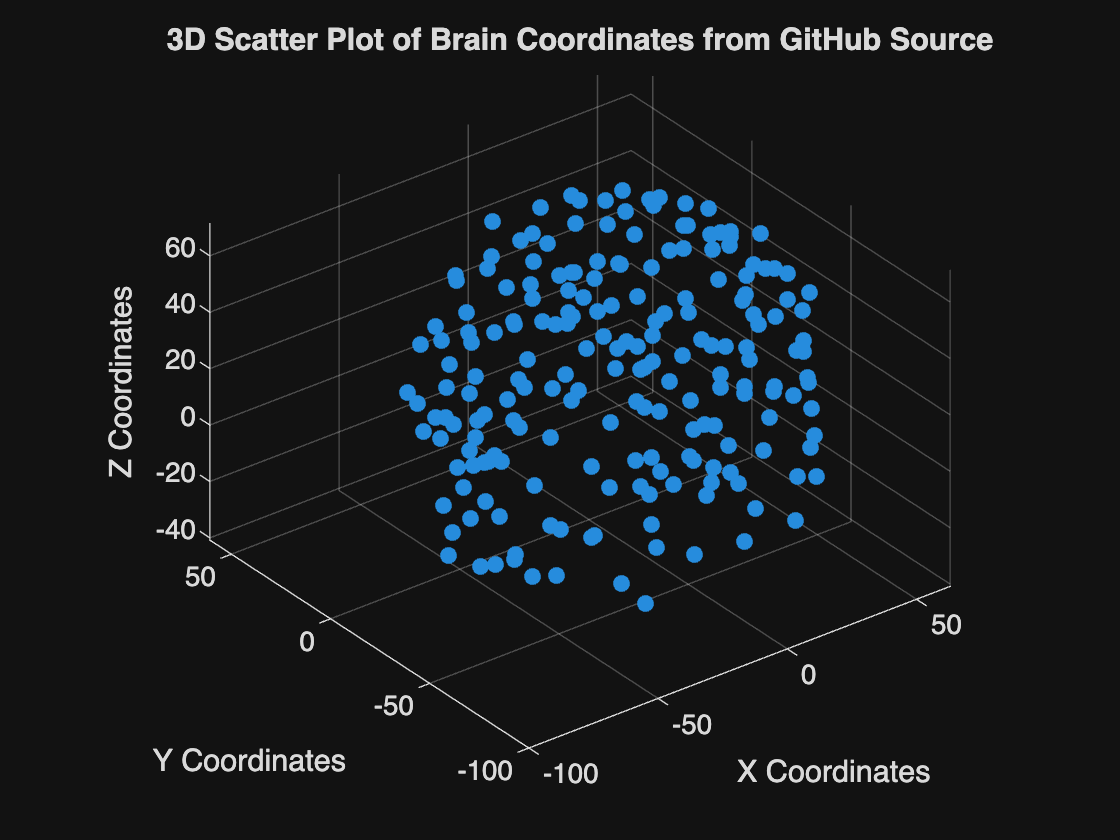


figure;

%3D Scatter Plot 

scatter3(L(:,1), L(:,2), L(:,3), 'filled'); % use 'filled' parameter to specify the points must be filled, leave this out if you want the coordinates to be empty
daspect([1, 1, 1]); % To keep same scale for x, y, z axes 

xlabel('X Coordinates'); % axis label  
ylabel('Y Coordinates'); % axis label 
zlabel('Z Coordinates'); % axis label 

title('3D Scatter Plot of Brain Coordinates from GitHub Source'); 
grid on;



%% 2
table_MEG = readtable('https://raw.githubusercontent.com/safiy-va/MatLab-Code-for-Brain-as-a-Matrix---Transformations-and-Visualization-/refs/heads/main/megdata.csv')

table_MEG = 500×201 table
    Time     LH_VisCent_ExStr_1    LH_VisCent_ExStr_2    LH_VisCent_Striate_1    LH_VisCent_ExStr_3    LH_VisCent_ExStr_4    LH_VisCent_ExStr_5    LH_VisPeri_ExStrInf_1    LH_VisPeri_ExStrInf_2    LH_VisPeri_ExStrInf_3    LH_VisPeri_StriCal_1    LH_VisPeri_ExStrSup_1    LH_VisPeri_ExStrSup_2    LH_SomMotA_1    LH_SomMotA_2    LH_SomMotA_3    LH_SomMotA_4    LH_SomMotA_5    LH_SomMotA_6    LH_SomMotA_7    LH_SomMotA_8    LH_SomMotB_Aud_1    LH_SomMotB_Aud_2    LH_SomMotB_S2_1    LH_SomMotB_S2_2    LH_SomMotB_Aud_3    LH


summary(table_MEG)


table_MEG: 500×201 table

Variables:

    Time: double
    LH_VisCent_ExStr_1: double
    LH_VisCent_ExStr_2: double
    LH_VisCent_Striate_1: double
    LH_VisCent_ExStr_3: double
    LH_VisCent_ExStr_4: double
    LH_VisCent_ExStr_5: double
    LH_VisPeri_ExStrInf_1: double
    LH_VisPeri_ExStrInf_2: double
    LH_VisPeri_ExStrInf_3: double
    LH_VisPeri_StriCal_1: double
    LH_VisPeri_ExStrSup_1: double
    LH_VisPeri_ExStrSup_2: double
    LH_SomMotA_1: double
    LH_SomMotA_2: double
    LH_SomMotA_3: double
    LH_SomMotA_4: double
    LH_SomMotA_5: double
    LH_SomMotA_6: double
    LH_SomMotA_7: double
    LH_SomMot


time = table_MEG.Time % converting the column of Time into a 500 x 1 matrix named time. 

time =          0
    0.0040
    0.0080
    0.0120
    0.0160
    0.0200
    0.0240
    0.0280
    0.0320
    0.0360
    0.0400
    0.0440
    0.0480
    0.0520
    0.0560



S = table2array(table_MEG);
% Extracted the recorded signals into a matrix named `S` in the line above 
S = table2array(table_MEG(:, 2:end));
 % Now, Excluding the first column--Time--to get only the signals that we want 

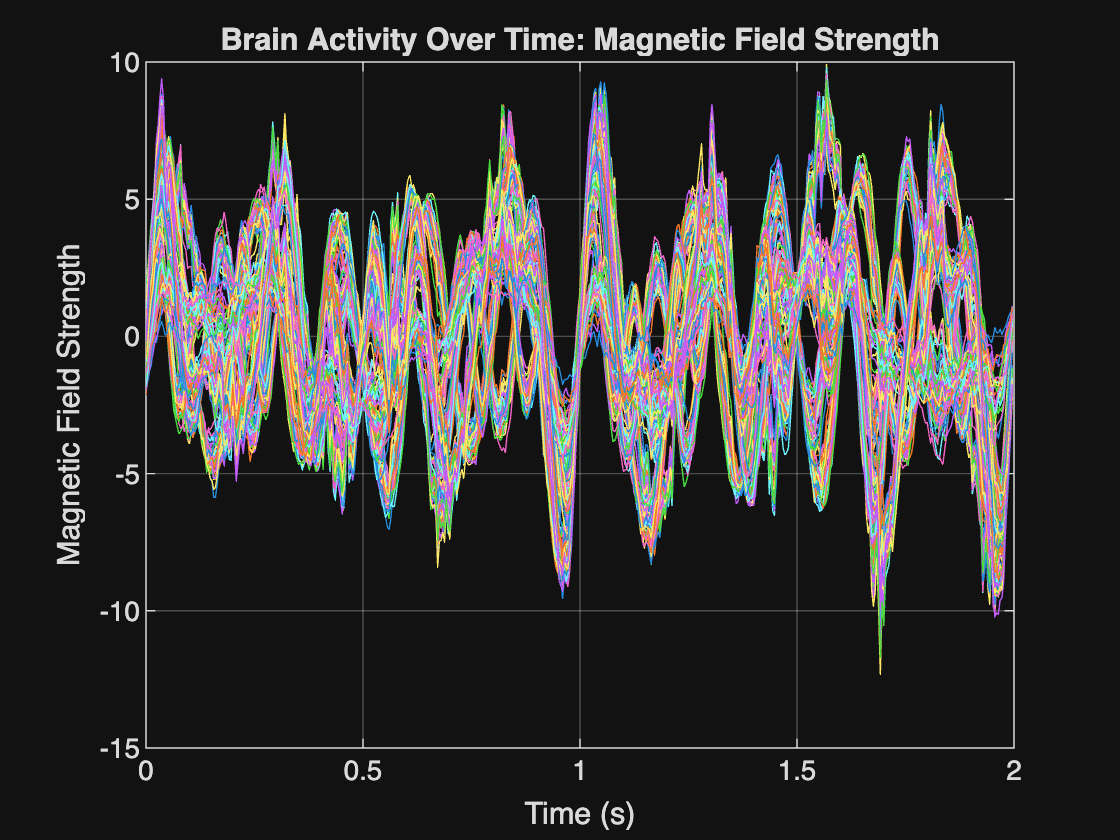


 figure;

plot(time, S); % Plotting the brain activity over time
xlabel('Time (s)'); % Label for the x-axis
ylabel('Magnetic Field Strength'); % Label for the y-axis
title('Brain Activity Over Time: Magnetic Field Strength'); % Title for the plot/figure 
grid on; % Enabling grid for enhancing visualization!!

%-------Mapping Subject Coordinates into Template Brain Space-----
% Source and target coordinates
target_nose_mm = [1; 91; -28];
source_nose_mm = [1.5; 85.3; -20.2];

target_earl_mm = [-83; -19; -47];
source_earl_mm = [-81.7; -15.6; -53.0];

target_earr_mm = [83; -19; -47];
source_earr_mm = [85.4; -16.2; -50.7];
A = [target_nose_mm, target_earl_mm, target_earr_mm] * inv([source_nose_mm, source_earl_mm, source_earr_mm]); % from rearranging above equation to solve for A
Target_coordinates = (A * L')' % transposing first and then again, 3 * N and N * 3 

Target_coordinates =   -36.9921  -55.2930   -3.6931
  -44.3790  -79.9315   -5.0192
  -63.3046  -71.3517    0.1523
  -25.1893  -69.4938    3.3173
  -48.1780  -98.2368   -1.2468
  -24.1305  -44.8746    2.8052
  -26.1774  -94.0381    5.7437
  -64.7539  -70.6581   17.4073
  -43.3699  -97.5990   15.9319
  -27.2807  -71.0675   15.0355
  -59.4206  -85.0282   18.7507
  -27.2156  -72.5848   28.6427
  -24.1858  -88.7536   35.9611
  -43.0992  -88.7364   32.3610
  -53.0750   -3.6951   -0.8662


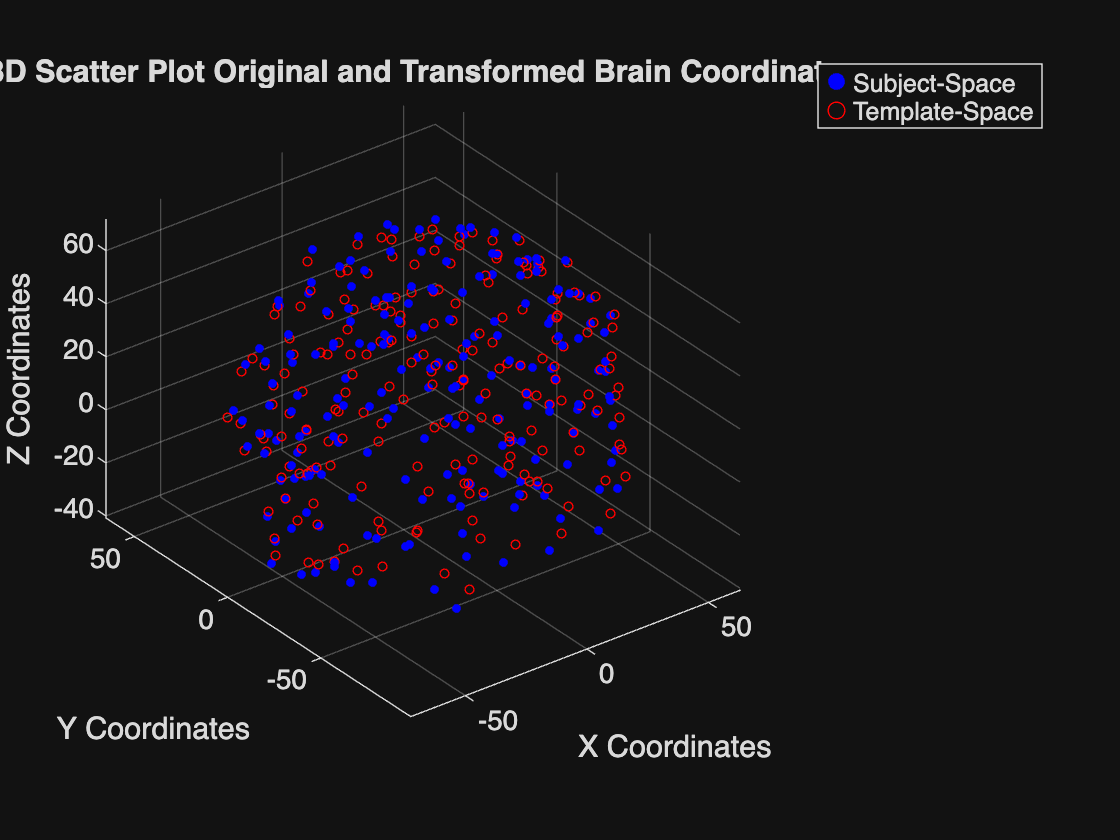

figure;

% OG coordinates 
scatter3(L(:,1), L(:,2), L(:,3), 10, 'b', 'filled');
hold on

% Transformed coordinates after applying matrix A 
scatter3(Target_coordinates(:,1), Target_coordinates(:,2), Target_coordinates(:,3), 10, 'r'); % unfilled to make easier to distinguish 

xlabel('X Coordinates');
ylabel('Y Coordinates');
zlabel('Z Coordinates');

legend('Subject-Space', 'Template-Space');

grid on;

title('3D Scatter Plot Original and Transformed Brain Coordinates');

axis equal;

daspect([1 1 1]); % even spacing 

view(3);

%% ------------Principal Component Analysis: Extracting Major Brain Activity Patterns-----------

% normalize each column
S_norm = zscore(S, [], 1);

% calculate the covariance matrix
C = cov(S_norm);

[eigen_vectors, eigenvalues_in_matrix] = eig(C)

eigen_vectors =     0.0711    0.2036    0.0631    0.0081    0.1742   -0.0656   -0.0343    0.0295    0.0213    0.1673    0.0336    0.2163    0.0645    0.0419   -0.0942   -0.0615    0.1629    0.0387    0.0872   -0.0958    0.0027   -0.0258    0.0674    0.0162    0.0474    0.0647   -0.0921   -0.0622   -0.0164    0.0654    0.0475   -0.1866   -0.1102    0.1397   -0.0898    0.0057   -0.0014    0.0265    0.0046   -0.0143   -0.0881    0.1328   -0.0238    0.0598   -0.0559   -0.1042   -0.0417   -0.0216    0.0796   -0.0901
    0.1110   -0.3233    0.0391    0.0788    0.1357    0.0252    0.0331   -0.1234   -0.0986    0.0286    0.0339   -0.1306    0.0024    0.0490   -0.1143    0.1302    0.0840   -0.0059    0.0664    0.1441    0.1898    0.0106   -0.0288    0.0614    0.0518    0.0296    0.0796   -0.0096   -0.0064    0.0878    0.0664   -0.1623   -0.0056    0.2554   -0.0590   -0.1547   -0.0862   -0.1249   -0.1373    0.0044    0.0057    0.0300   -0.0253   -0.0033    0.0058   -0.0170    0.1317    0.1002   

eigenvalues_in_matrix =     0.0002         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0    0.0002         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0     


eigen_values = diag(eigenvalues_in_matrix) % extraction of eigen values - they are in ascending order currently 

eigen_values =     0.0002
    0.0002
    0.0003
    0.0003
    0.0003
    0.0003
    0.0003
    0.0003
    0.0003
    0.0003
    0.0004
    0.0004
    0.0004
    0.0004
    0.0004



[eigenvalues_sorted, sort_idx] = sort(eigen_values, 'descend') % sorting in descending order 

eigenvalues_sorted =   102.0495
   33.1212
   25.8417
   20.8073
   12.7233
    4.0206
    0.3889
    0.1811
    0.1001
    0.0469
    0.0455
    0.0313
    0.0194
    0.0180
    0.0161


sort_idx =    200
   199
   198
   197
   196
   195
   194
   193
   192
   191
   190
   189
   188
   187
   186



eigenvectors_sorted = eigen_vectors(:, sort_idx)

eigenvectors_sorted =     0.0828    0.0011    0.0915   -0.0496    0.0323    0.0583   -0.0953   -0.0062    0.0722   -0.0068    0.0355    0.0069   -0.0154    0.0084    0.0088    0.0178    0.0038   -0.0013    0.0324    0.0269   -0.0286   -0.0483    0.0130   -0.0590    0.0226    0.0084   -0.0431   -0.0088   -0.0054    0.0169    0.0090    0.0120    0.0176   -0.0367    0.0704   -0.0086   -0.0042   -0.0503   -0.0601   -0.0437   -0.0306    0.0153    0.0647   -0.0686    0.0362    0.0005    0.0039    0.0380    0.0163   -0.0345
    0.0838    0.0090    0.0912   -0.0362    0.0445    0.0533   -0.0383    0.0021    0.0052   -0.0656   -0.0101   -0.0358    0.0037    0.0094    0.0242    0.0061   -0.0064    0.0505    0.0148   -0.0099   -0.0118    0.0229    0.0115    0.0056    0.0039    0.0052    0.0074   -0.0233   -0.0183   -0.0264   -0.0386    0.0107    0.0230   -0.0133    0.0111    0.0213   -0.0378   -0.0129    0.0366    0.0295    0.0781   -0.0253   -0.0584   -0.0413    0.0016   -0.0154   -0.0044   -0.0

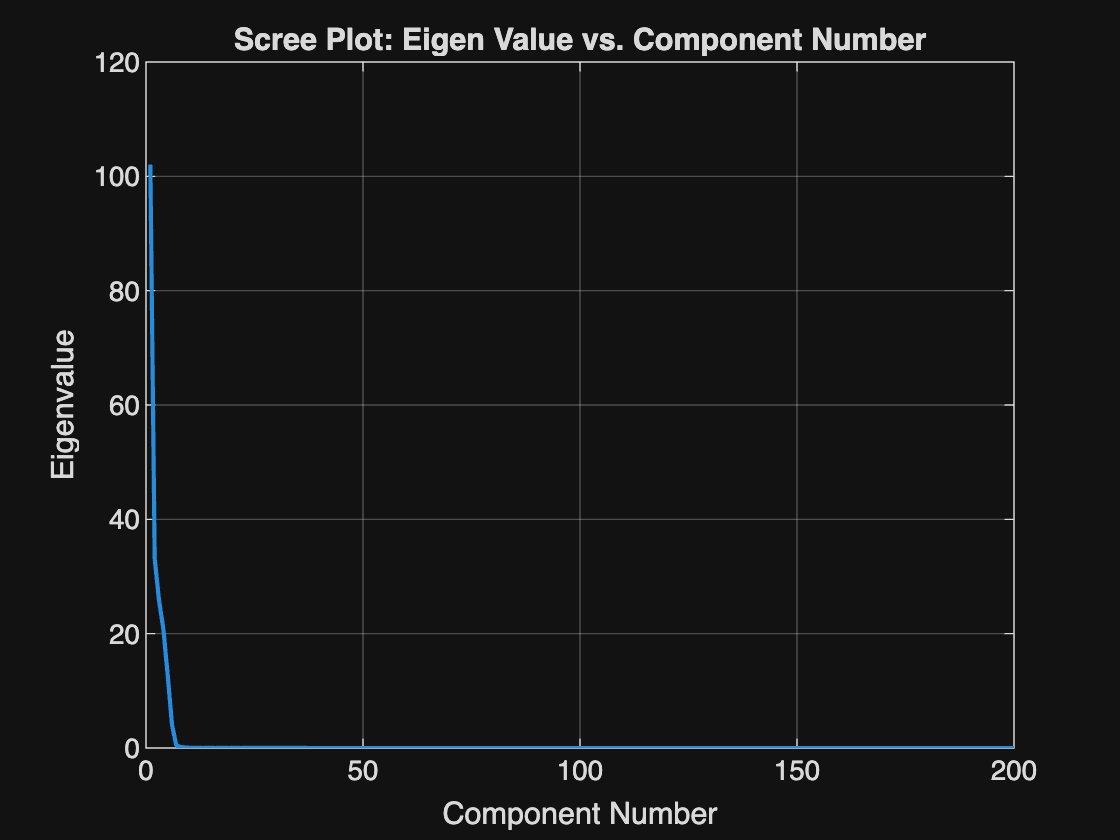


figure;

plot(eigenvalues_sorted, 'LineWidth', 1.5); % plotting with formatting parameters 

% Title Label 
title('Scree Plot: Eigen Value vs. Component Number'); 

% Axes 

xlabel('Component Number');
ylabel('Eigenvalue');

grid on;

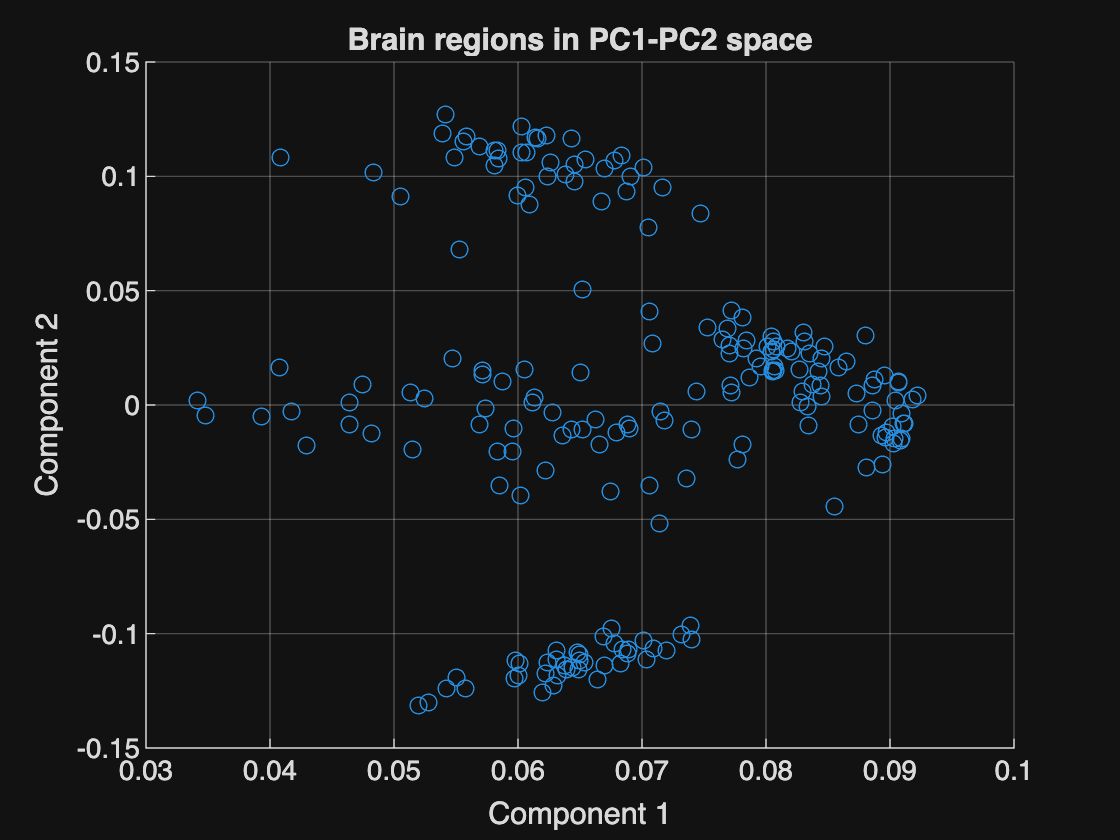


figure;
scatter(eigenvectors_sorted(:,1), eigenvectors_sorted(:,2));
xlabel('Component 1');
ylabel('Component 2');
title('Brain regions in PC1-PC2 space');
grid on;


projected_measurements = S_norm * eigenvectors_sorted

projected_measurements =    -2.3453   -1.7539   -2.9336   -2.7215    3.6603   -0.1349    0.2466   -0.0804   -0.6769    0.4584   -0.1114   -0.1533    0.5175   -0.1253   -0.2664   -0.1759   -0.3303    0.0590    0.0274    0.1241    0.0881   -0.0485   -0.0233    0.2869    0.0287   -0.1577    0.0242    0.1708   -0.0636   -0.2588   -0.1847   -0.0234   -0.0601   -0.1386    0.2457   -0.0675    0.0196   -0.0948   -0.0141   -0.0822   -0.0203   -0.0090   -0.0871   -0.0924    0.0088   -0.0865   -0.0309   -0.0046   -0.1007    0.1061
    0.6261   -1.6816   -3.5110   -1.8573    3.4830   -0.4330    0.2502   -0.0260   -0.5450    0.3941   -0.0630   -0.0131    0.1863   -0.1028   -0.2163   -0.0396   -0.0351   -0.0449   -0.0036    0.0409    0.1445    0.0588   -0.0735    0.1853   -0.1561   -0.2244    0.0588    0.1212   -0.0351   -0.1624   -0.0596   -0.1262   -0.1249   -0.0777    0.0150    0.0761   -0.0334   -0.0043    0.2169   -0.0469    0.0252   -0.0416   -0.1702   -0.0384   -0.0560    0.0122    0.0680   -


PC1_amplitude = projected_measurements(:, 1)

PC1_amplitude =    -2.3453
    0.6261
    4.5819
    8.1319
   10.6294
   14.0446
   17.8757
   19.6511
   22.0322
   24.0546
   22.2573
   17.6857
   15.4105
   17.2341
   16.6329


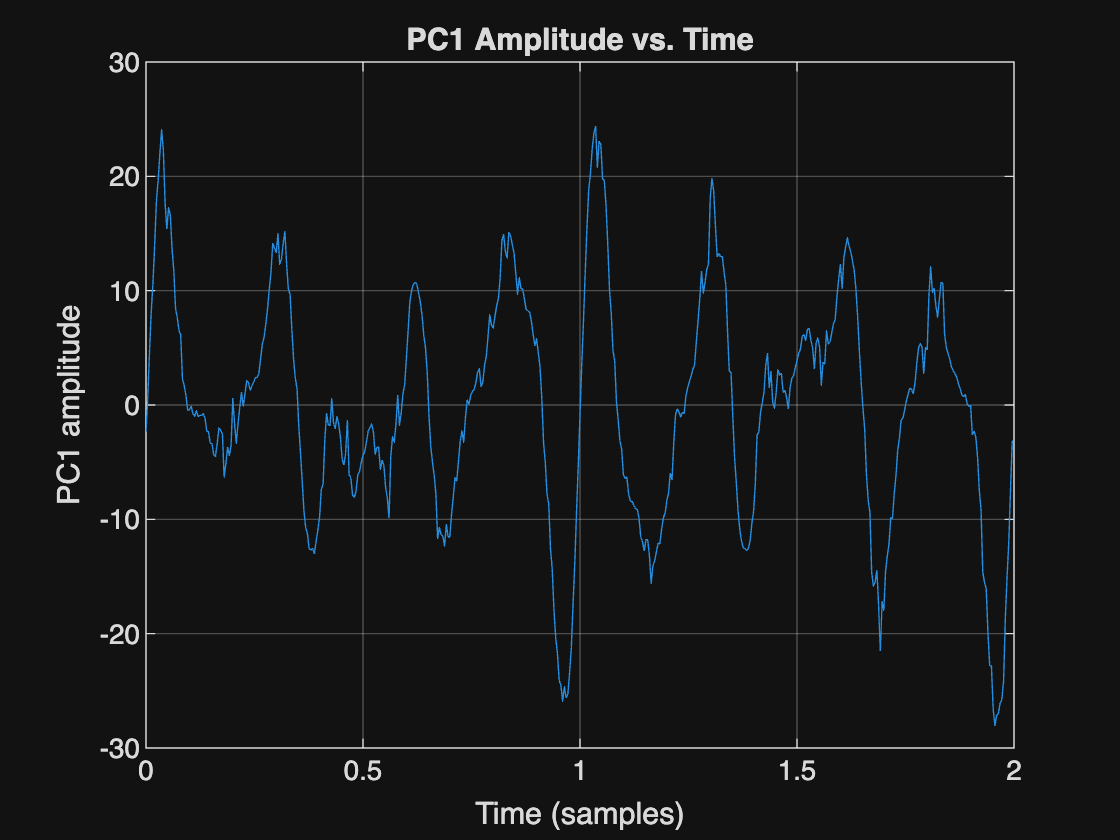


figure;
plot(time, PC1_amplitude);
xlabel('Time (samples)');
ylabel('PC1 amplitude');
title('PC1 Amplitude vs. Time');
grid on;

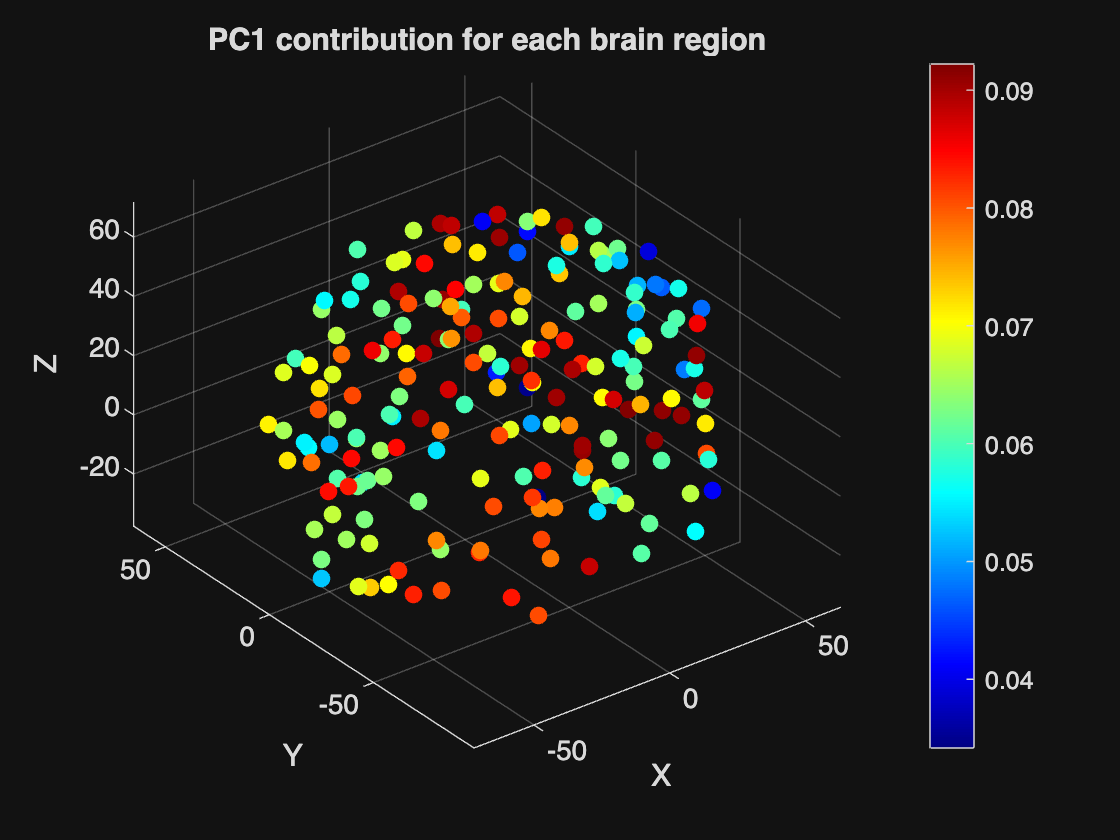


figure;

scatter3(Target_coordinates(:,1), Target_coordinates(:,2), Target_coordinates(:,3), 40, abs(eigenvectors_sorted(:,1)), 'filled');
colorbar;
colormap jet;
axis equal;
xlabel('X'); ylabel('Y'); zlabel('Z');
title('PC1 contribution for each brain region');

%%-------Brain–Behaviour Relationship Analysis Using Linear Regression-------

%% 3 
meg_x_neuropsych = readtable("https://raw.githubusercontent.com/safiy-va/MatLab-Code-for-Brain-as-a-Matrix---Transformations-and-Visualization-/refs/heads/main/meg_with_neuropsych.csv")

meg_x_neuropsych = 50×5 table
     Age      TOVA_Score    PVT_Mean_RT_ms    ASRS_Score    MEG_PC1_fT
    ______    __________    ______________    __________    __________

    12.244      111.08          304.85           32.73        310.43  
     20.31      102.57          348.43          45.686        394.63  
    17.248      98.265           264.9           10.71        339.83  
    15.381      95.483          283.62          32.216        284.65  
    9.1843      77.822          280.39          33.119        204.51  
    9.1839      89.202          226.82          39.382        238.78  
    7.8132       93.09          314.81          15.157        209.96  
    19.126      115.86          313.05          14.155        403.82  
    15.416      105.15          300.26          36.263        336.59  
    16.913      73

numParticipants = size(meg_x_neuropsych, 1);
ageColumn = table2array(meg_x_neuropsych(:, 1));
interceptColumn = ones(numParticipants, 1);
designRow = [ageColumn ; interceptColumn]';
% reshape to 50×2 m with ages and intercept)
A = reshape(designRow, numParticipants, 2)

A =    12.2436    1.0000
   20.3100    1.0000
   17.2479    1.0000
   15.3812    1.0000
    9.1843    1.0000
    9.1839    1.0000
    7.8132    1.0000
   19.1265    1.0000
   15.4156    1.0000
   16.9130    1.0000
    7.2882    1.0000
   20.5787    1.0000
   18.6542    1.0000
    9.9727    1.0000
    9.5455    1.0000



% vector b (col 5)
b = table2array(meg_x_neuropsych(:, 5))

b =   310.4326
  394.6329
  339.8334
  284.6462
  204.5067
  238.7769
  209.9587
  403.8159
  336.5888
  244.1374
  260.6083
  369.3795
  349.0454
  312.7331
  276.4338



x1 = (A' * A) \ (A' * b)

x1 =     9.4524
  177.1018



line_of_best_fit_ages = x1(1) * ageColumn + x1(2)

line_of_best_fit_ages =   292.8333
  369.0807
  340.1366
  322.4918
  263.9154
  263.9123
  250.9553
  357.8935
  322.8169
  336.9710
  245.9929
  371.6210
  353.4294
  271.3686
  267.3305


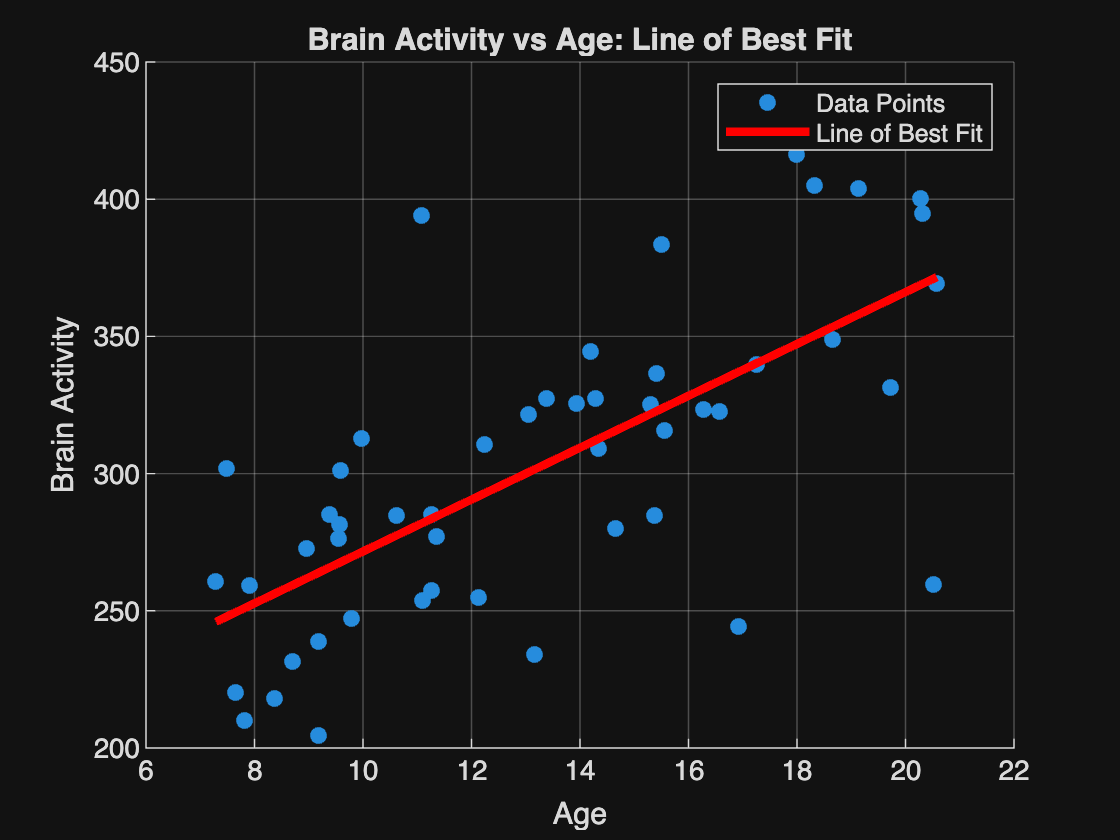


figure; 

% # real data 
scatter(ageColumn, b, 'filled');
hold on;

% line of best fit
plot(ageColumn, line_of_best_fit_ages, 'r', 'LineWidth', 3);

xlabel('Age');
ylabel('Brain Activity');
title('Brain Activity vs Age: Line of Best Fit');

legend('Data Points', 'Line of Best Fit');
grid on;

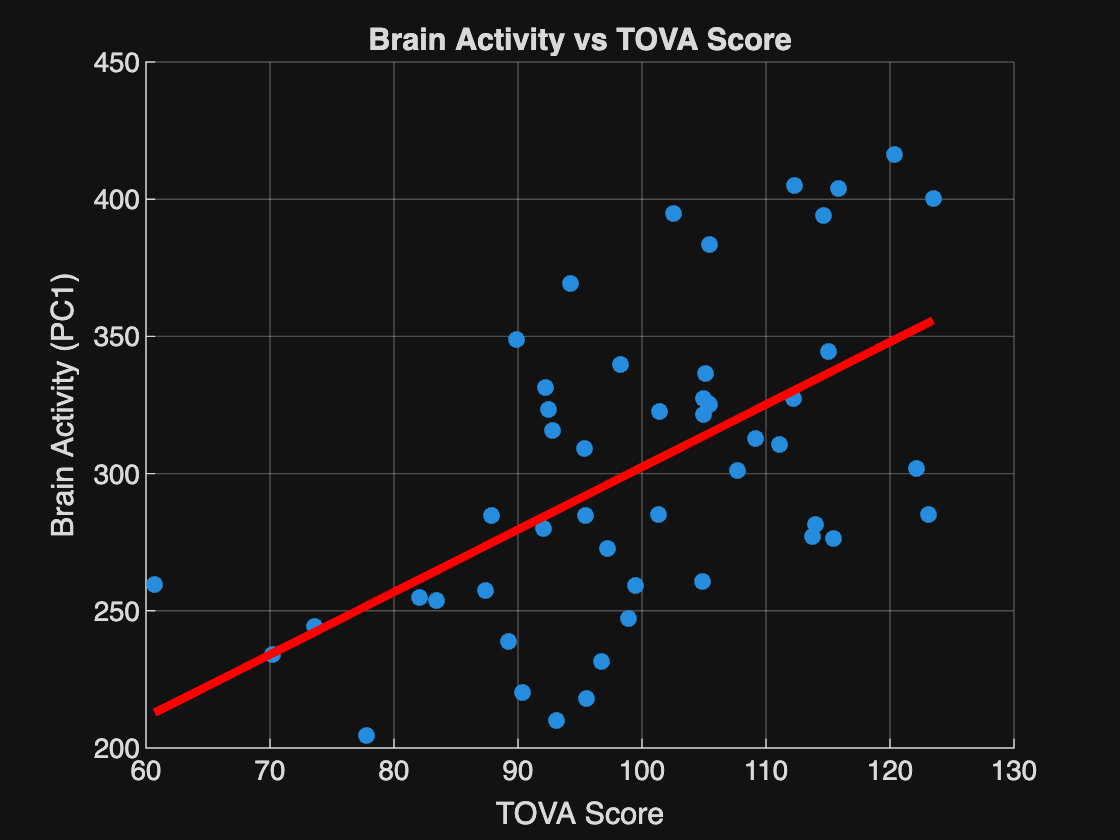


% -- TOVA: col 2
tova_scores = table2array(meg_x_neuropsych(:, 2));   
designRow_tova = [tova_scores ; interceptColumn]';   
A2 = reshape(designRow_tova, numParticipants, 2);     
x2 = (A2' * A2) \ (A2' * b);                         
line_of_best_fit_tova = x2(1) * tova_scores + x2(2); % line of best fit 

% repeating for every one 

% PVT --- col 3 
pvt_mean = table2array(meg_x_neuropsych(:, 3));      
designRow_pvt = [pvt_mean ; interceptColumn]';
A3 = reshape(designRow_pvt, numParticipants, 2);
x3 = (A3' * A3) \ (A3' * b);
line_of_best_fit_pvt = x3(1) * pvt_mean + x3(2); % line of best fit 

% ASRS --- column 4 
asrs_score = table2array(meg_x_neuropsych(:, 4));  
designRow_asrs = [asrs_score ; interceptColumn]';
A4 = reshape(designRow_asrs, numParticipants, 2);
x4 = (A4' * A4) \ (A4' * b);
line_of_best_fit_asrs = x4(1) * asrs_score + x4(2);

% TOVA =========

figure;
scatter(tova_scores, b, 'filled');
hold on;
plot(tova_scores, line_of_best_fit_tova, 'r', 'LineWidth', 3);
title('Brain Activity vs TOVA Score');
xlabel('TOVA Score');
ylabel('Brain Activity (PC1)');
grid on;

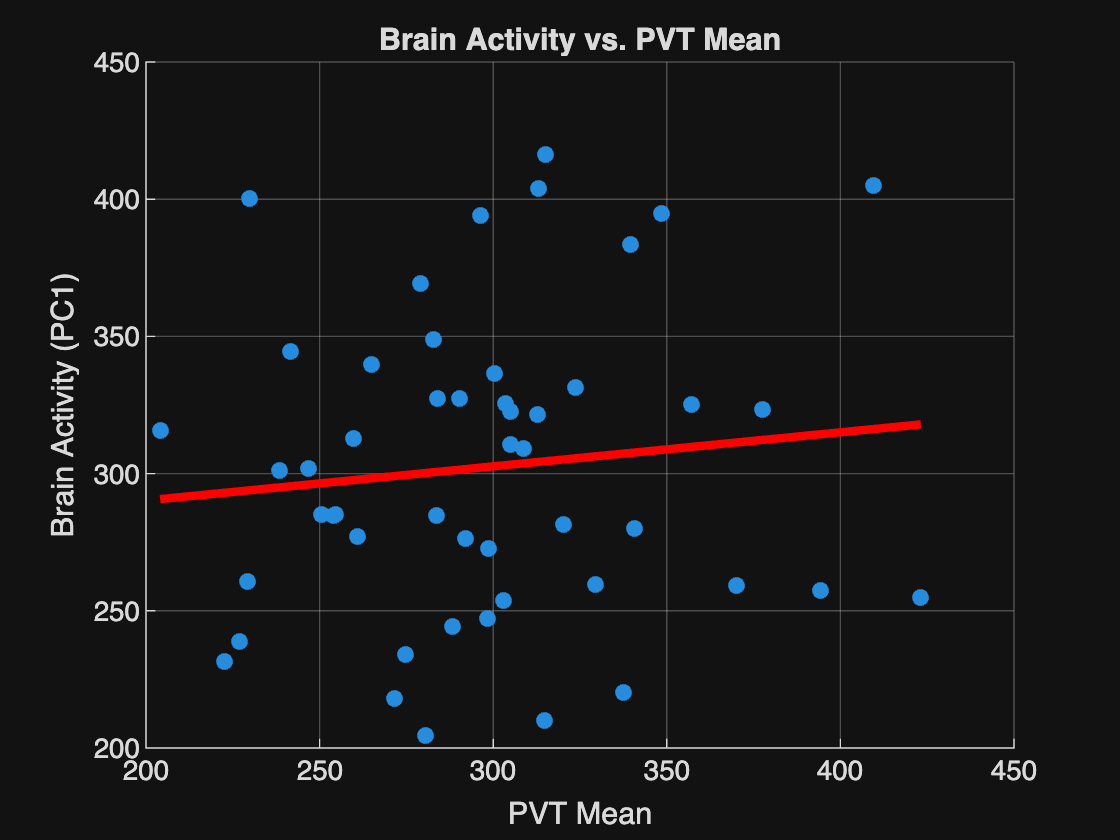


%PVT Mean =====

figure;
scatter(pvt_mean, b, 'filled');
hold on;
plot(pvt_mean, line_of_best_fit_pvt, 'r', 'LineWidth', 3);
title('Brain Activity vs. PVT Mean');
xlabel('PVT Mean');
ylabel('Brain Activity (PC1)');
grid on;

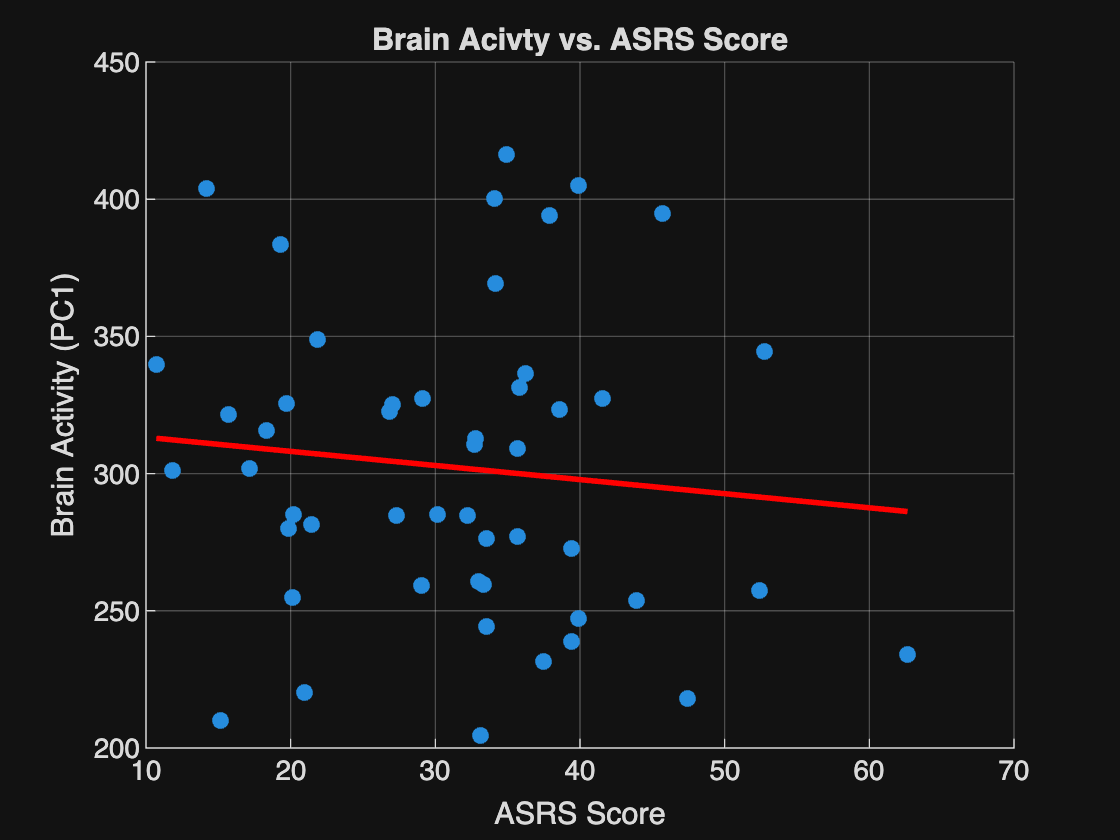


%ASRS Score =======

figure;
scatter(asrs_score, b, 'filled');
hold on;
plot(asrs_score, line_of_best_fit_asrs, 'r', 'LineWidth', 2);
title('Brain Acivty vs. ASRS Score');
xlabel('ASRS Score');
ylabel('Brain Activity (PC1)');
grid on;